# Iterative fitting for multiple waves

In this example, the generalized SEIR model is automatically fitted to multiple provinces in China. As in the previous examples, I am taking some data, collected into DATA.mat from John Hopkins university [1]. To keep the computation as short as possible, the option "iter" is removed using an optional argument.

**Only Provinces with multiple epidemic waves are selected**

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Load the data

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();
timeRef = time;
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 17-May-2021




Location = 'United Arab Emirates';

try
    indR = find(contains(tableRecovered.CountryRegion,Location)==1);
    indC = find(contains(tableConfirmed.CountryRegion,Location)==1);
    indD = find(contains(tableDeaths.CountryRegion,Location)==1);
catch exception
    searchLoc = strfind(tableRecovered.CountryRegion,Location);
    indR = find(~cellfun(@isempty,searchLoc)) ;
    searchLoc = strfind(tableConfirmed.CountryRegion,Location);
    indC = find(~cellfun(@isempty,searchLoc)) ;
    
    searchLoc = strfind(tableDeaths.CountryRegion,Location);
    indD = find(~cellfun(@isempty,searchLoc));
end

disp(tableConfirmed(indC,1:2))

    ProvinceState        CountryRegion     
    _____________    ______________________

      <missing>      "United Arab Emirates"



##  Initial guess and initial conditions

% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 0.9; % Infection rate
LT_guess = 5; % latent time in days
Q_guess = 0.1; % rate at which infectious people enter in quarantine
lambda_guess = [0.1,0.1,20]; % recovery rate
kappa_guess = [0.005,0.005,10]; % death rate
guess = [alpha_guess,beta_guess,1/LT_guess,Q_guess,lambda_guess,kappa_guess];

Npop= 10e6; % population


## Main loop

The intiial number of exposed and infectious has a non-negligible influence on the outcome of the fit. A poor fit can be linked to the wrong choice of E0 and I0

Note that a poor estimate for the beginning of the second wave implies a poor fit for the second wave, as highlighted below. Version 4.8.8 includes a slightly more robust fit, which is also more time consuming.

tStart1 = datetime(2020,05,01); % Beginning of the first wave
tStart2 = datetime(2020,11,06); % Beginning of the second wave
tEnd = datetime(2021,03,01); % End of simulation


time = timeRef;
Recovered = table2array(tableRecovered(indR,5:end));
Deaths = table2array(tableDeaths(indD,5:end));
Confirmed = table2array(tableConfirmed(indC,5:end));

indT = find(time>=tStart1 & time <=tEnd);
Recovered=Recovered(indT);
Deaths = Deaths(indT);
time = time(indT);
Confirmed = Confirmed(indT);

Active = Confirmed-Recovered-Deaths;
Active(Active<0) = 0; % No negative number possible



[Q,R,D,newT] = getMultipleWaves(guess,Npop,time,Confirmed,Recovered,Deaths,...
    tStart1,tStart2,tEnd);

Fitting succeded. Check the initial value of E0 and I0 


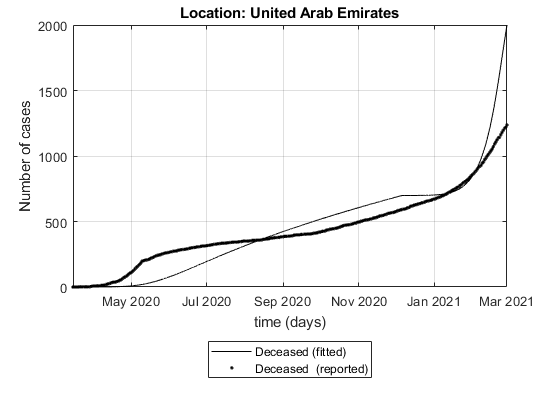

checkRates(time,Active,Recovered,Deaths,kappaFun,lambdaFun,Kappa1,Lambda1);
clf;close all;
figure
semilogy(newT,D,'k');
hold on
semilogy(time,Deaths,'k.');
 ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {
    'Deceased (fitted)',...
   'Deceased  (reported)'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
    set(gca,'yscale','lin')
try
    subLoc = char(table2array(tableRecovered(indR,1)));
    Loc = char(table2array(tableRecovered(indR,2)));
    title(['Location: ',subLoc,' (',Loc,')'])
catch exception
    Loc = char(table2array(tableRecovered(indR,2)));
    title(['Location: ',Loc])
end